# 矩阵的秩

clc
clear all
close all

% 生成一个秩缺的3x3的方阵
A = [1, 0, 1;
     0, 1, 1;
     1, 0, 1];

% 生成一个满秩的3x3的方阵
B = [1, 0, 0;
     0, 1, 0;
     1, 0, 1];

## 数学含义

### 1. 行列式不为0的最大子方阵维数

#### **秩缺的情况**

Rank_A = rank(A)

Rank_A = 2

Det_A = det(A)

Det_A = 0


% 循环遍历3x3矩阵的每一个2x2子方阵
for i = 1:2
    for j = 1:2
        % 选择2x2子方阵
        sub_A = A(i:i+1, j:j+1) 
        % 计算子方阵的行列式
        Det_sub_A = det(sub_A)
    end
end

sub_A =      1     0
     0     1


Det_sub_A = 1

sub_A =      0     1
     1     1


Det_sub_A = -1

sub_A =      0     1
     1     0


Det_sub_A = -1

sub_A =      1     1
     0     1


Det_sub_A = 1

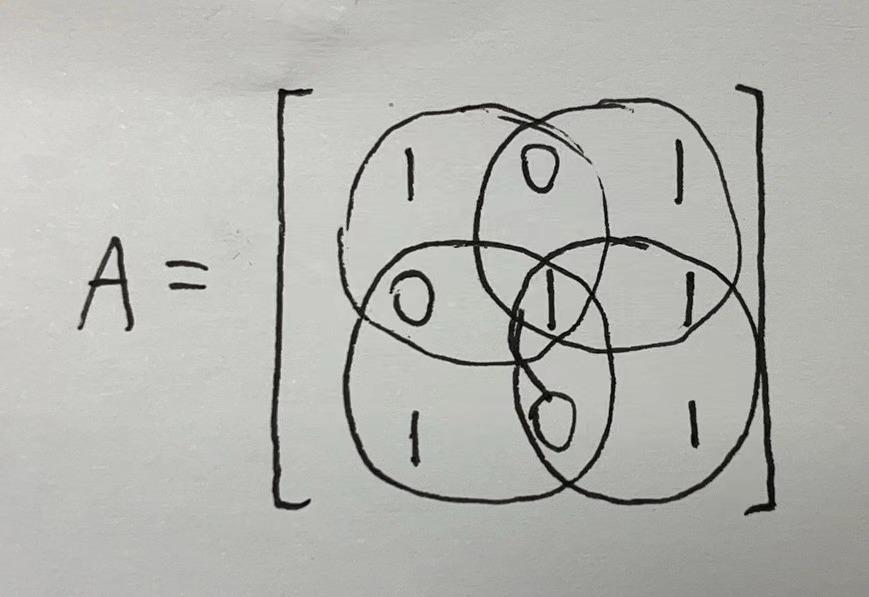

**满秩的情况**

Rank_B = rank(B)

Rank_B = 3

Det_B = det(B)

Det_B = 1

### **2. 列向量组（行向量组）中最大的线性无关的向量个数**

% 提取列向量
A_col1 = A(:, 1); A_col2 = A(:, 2); A_col3 = A(:, 3);

% 提取行向量
A_row1 = A(1, :); A_row2 = A(2, :); A_row3 = A(3, :);

% 提取列向量
B_col1 = B(:, 1); B_col2 = B(:, 2); B_col3 = B(:, 3);

% 提取行向量
B_row1 = B(1, :); B_row2 = B(2, :); B_row3 = B(3, :);

假设x=[x1 x2 x3]'

A*x可以理解为对A的3个列向量[1 0 1]'、[0 1 1]'和[0 0 0]'进行**线性组合**

得到b = x1*[1 0 1]'+x2*[0 1 1]'+x3*[1 1 1]'

如果能选择**非零的**x1、x2和x3,，使得b = [0 0 0]'

则说明A的列向量线性相关（注：这个x在A的**零空间**中）

% 生成3x1的零向量x
x = zeros(3, 1);

% 解矩阵方程A*x=0
solution = A \ x

solution =    NaN
   NaN
   NaN


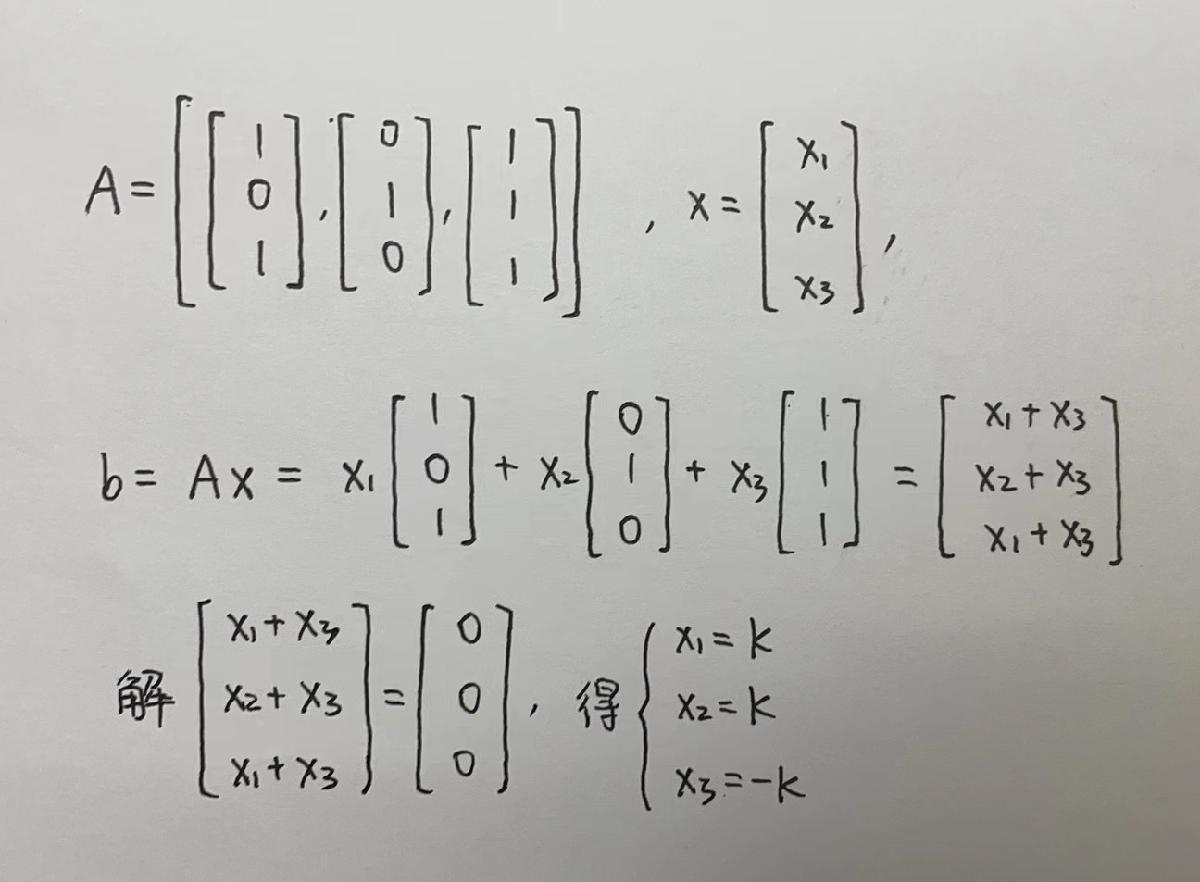

### **3. 列向量组（行向量组）张成的线性空间的维数**

**秩缺的情况**

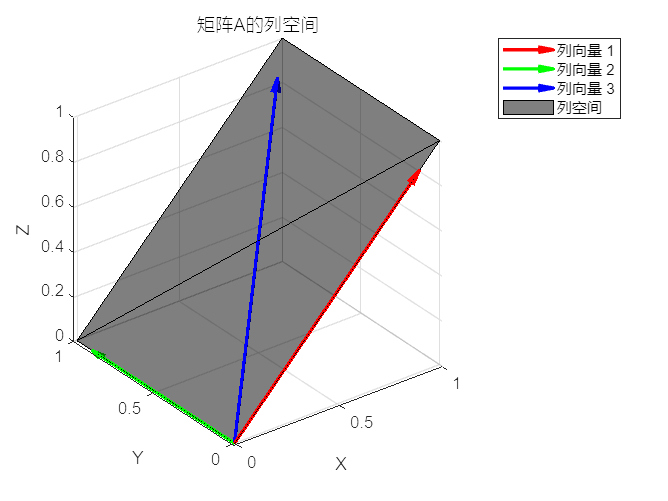

% 创建一个新图形
figure;

% 绘制列向量
quiver3(0, 0, 0, A_col1(1), A_col1(2), A_col1(3), 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, A_col2(1), A_col2(2), A_col2(3), 'g', 'LineWidth', 2);
quiver3(0, 0, 0, A_col3(1), A_col3(2), A_col3(3), 'b', 'LineWidth', 2);

% 设置图形属性
xlabel('X'); ylabel('Y'); zlabel('Z');
title('矩阵A的列空间');

[x, y, z] = meshgrid(0:1:1, 0:1:1, 0:1:1);
% 创建平面方程
plane = x - z;
h = isosurface(x, y, z, plane, 0);
p = patch(h);
alpha(p, 0.5);  % 这里设置透明度为0.5

% 设置图形属性
axis equal;

% 显示图例
legend('列向量 1', '列向量 2', '列向量 3', '列空间');

hold off;

观察图中A的3个列向量[1 0 1]'、[0 1 1]'和[1 1 1]'张成的空间，是一个二维平面。

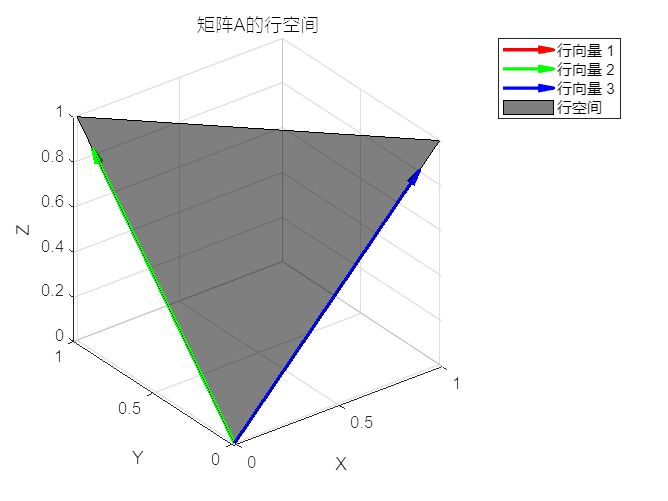

% 创建一个新图形
figure;

% 绘制行向量
quiver3(0, 0, 0, A_row1(1), A_row1(2), A_row1(3), 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, A_row2(1), A_row2(2), A_row2(3), 'g', 'LineWidth', 2);
quiver3(0, 0, 0, A_row3(1), A_row3(2), A_row3(3), 'b', 'LineWidth', 2);

% 设置图形属性
xlabel('X'); ylabel('Y'); zlabel('Z');
title('矩阵A的行空间');

[x, y, z] = meshgrid(0:1:1, 0:1:1, 0:1:1);
% 创建平面方程
plane = x +y- z;
h = isosurface(x, y, z, plane, 0);
p = patch(h);
alpha(p, 0.5);  % 这里设置透明度为0.5

% 显示图例
legend('行向量 1', '行向量 2', '行向量 3', '行空间');

grid on;
axis equal;

hold off;

A的3个行向量中，有两个重复，所以由2个不平行行向量张成一个二维平面。

**满秩的情况**

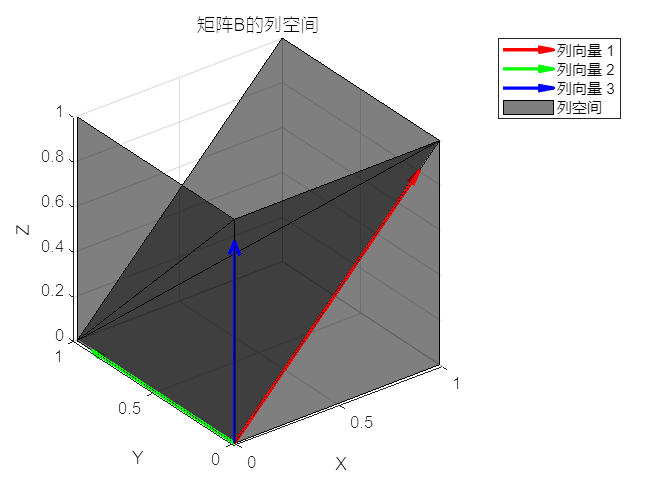

% 创建一个新图形
figure;

% 绘制列向量
quiver3(0, 0, 0, B_col1(1), B_col1(2), B_col1(3), 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, B_col2(1), B_col2(2), B_col2(3), 'g', 'LineWidth', 2);
quiver3(0, 0, 0, B_col3(1), B_col3(2), B_col3(3), 'b', 'LineWidth', 2);

% 设置图形属性
xlabel('X'); ylabel('Y'); zlabel('Z');
title('矩阵B的列空间');

[x, y, z] = meshgrid(0:1:1, 0:1:1, 0:1:1);
plane1 = x;
h1 = isosurface(x, y, z, plane1, 0);
p1 = patch(h1);
alpha(p1, 0.5);  % 这里设置透明度为0.5
plane2 = y;
h2 = isosurface(x, y, z, plane2, 0);
p2 = patch(h2);
alpha(p2, 0.5);  % 这里设置透明度为0.5
plane3 = x-z;
h3 = isosurface(x, y, z, plane3, 0);
p3 = patch(h3);
alpha(p3, 0.5);  % 这里设置透明度为0.5

% 显示图例
legend('列向量 1', '列向量 2', '列向量 3', '列空间');

grid on;
axis equal;

hold off;

观察图中B的3个列向量[1 0 1]'、[0 1 1]'和[0 0 1]'张成的空间，是一个三维空间。

行空间同理，这里不再赘述。

## 应用场景

### 1. 线性方程组的解

在线性代数中，矩阵的秩与线性方程组的解之间存在密切关系。如果一个线性方程组的系数矩阵的秩小于等于方程的未知数个数，那么该方程组可能有无穷多解，而秩等于未知数个数时，方程组有唯一解。

eqns = {
    'x + z = 1'
    'x + y = 1'
    'x + z = 1'
    };

% 定义右侧常数向量b
b = [1; 1; 1];

% 使用 linsolve 函数解方程组
x = linsolve(A, b)

x =    NaN
   NaN
   NaN


注意到该方程组有3个未知数，但系数矩阵A的秩为2，因此存在无穷多解。

eqns = {
    'x = 1'
    'y = 1'
    'x + z = 1'
    };

% 定义右侧常数向量b
b = [1; 1; 1];

% 使用 linsolve 函数解方程组
x = linsolve(B, b)

x =      1
     1
     0


注意到该方程组有3个未知数，而系数矩阵B的秩也为3，因此有唯一解。

### 2. 控制理论

在控制系统中，矩阵的秩用于分析系统的可控性和观测性。可控性矩阵和观测性矩阵的秩可以帮助工程师确定系统是否能够被有效地控制和观测。

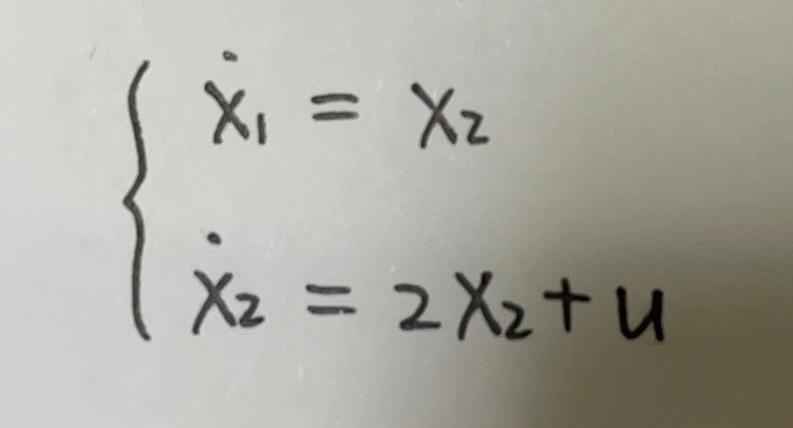          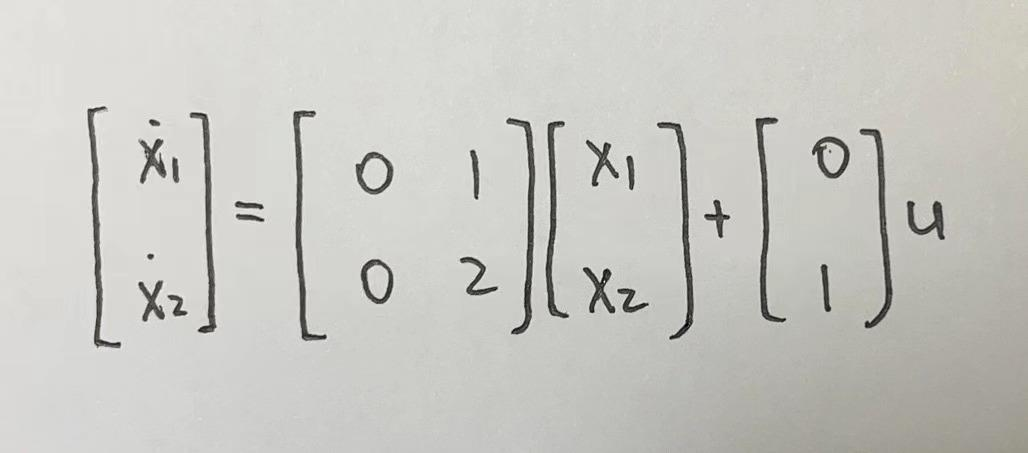

以一个简单的二阶系统（如：弹簧震动、RCL电路）为例，其P矩阵秩缺，意味着系统不可控。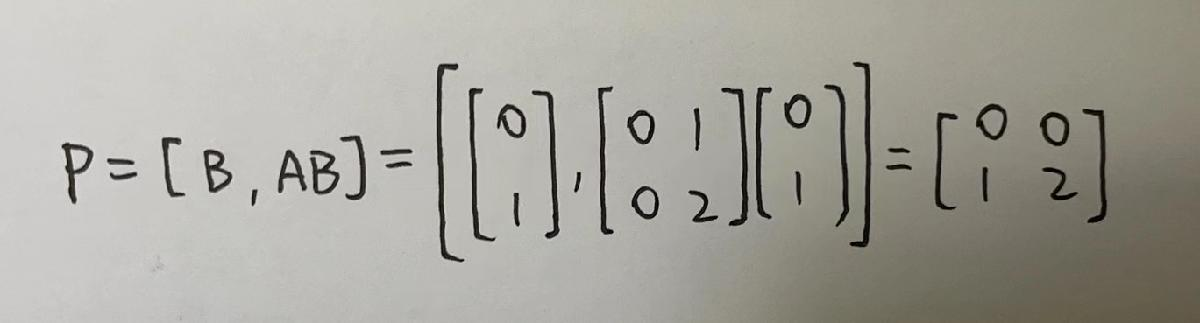

从直观的角度理解，x1无论如何变化，都不受输入u的影响（不受控制），因此整个系统是不可控的。

[3]TIM. ACnD 3. 可控性与可观测性 (Controllablity and Obeservablity)[EB/OL]. (2022-02-21)[2023-11-02]. https://zhuanlan.zhihu.com/p/467542401.

## 一些问题